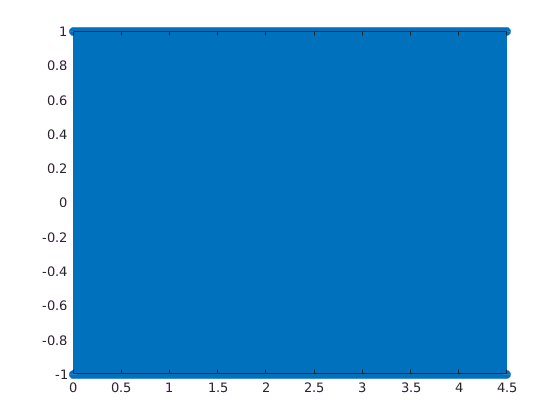

Fs = 600;                     % Sampling frequency
f0 = 300;                     % Fequency of the wave.
T = 1/Fs;                     % Sampling period
L = 2700;                     % Length of signal
t = (0:L-1)*T;                % Time vector
x = cos(2*pi*f0*t);          % Wave
stem(t,x);                    % Plot wave

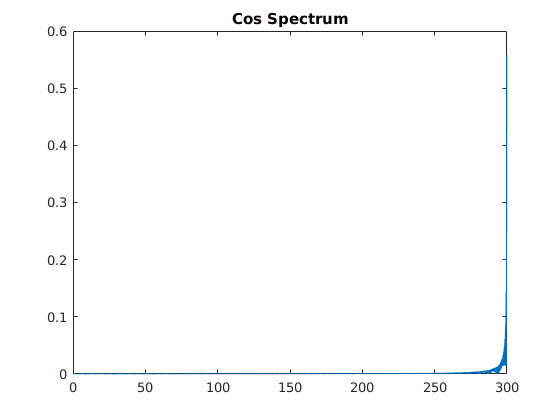

n = 2^nextpow2(L);
Y = fft(x,n);

P2 = abs(Y/n);
P1 = P2(:,1:n/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

plot(0:(Fs/n):(Fs/2-Fs/n),P1(1:n/2));
title("Cos Spectrum");

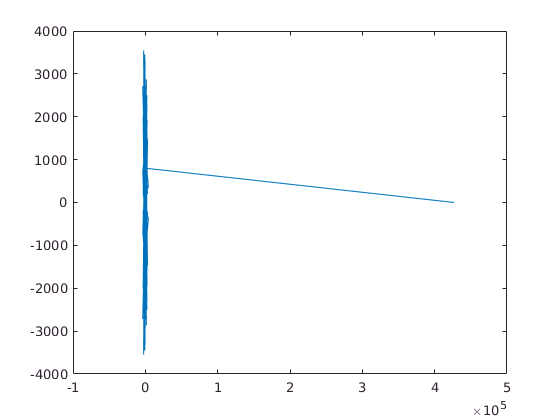

file_name = "test_rx.csv";
rx_read = csvread(file_name);
plot (fft(rx_read(:,1)));

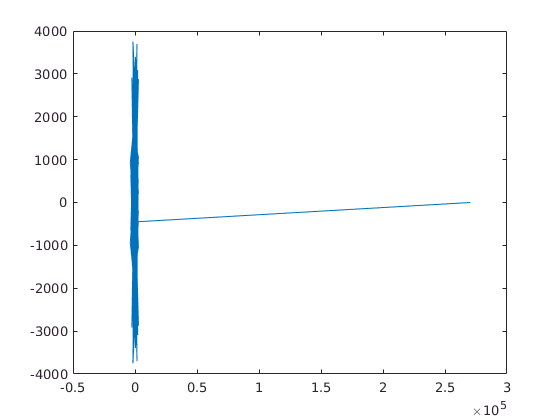

plot (fft(rx_read(:,2)));

Fs = 600;                     % Sampling frequency
f0 = 300;                     % Fequency of the wave.
T = 1/Fs;                     % Sampling period
L = 2700;                     % Length of signal
t = (0:L-1)*T;                % Time vector
n = 2^nextpow2(L);
Y = fft(x,n);

P2 = abs(Y/n);
P1 = P2(:,1:n/2+1);
P1(:,2:end-1) = 2*P1(:,2:end-1);

plot(0:(Fs/n):(Fs/2-Fs/n),P1(1:n/2));
title("Cos Spectrum");